## **Retinotopic Mapping: **

`This Live Script runs the retinotopy analysis function with specified parameters.`

**1) Define the input parameters of the imaging session: **

% Define the input parameters
subjectID    = 'SW12'; % Identifier for the subject
sessionDate  = '240514'; % Date of the imgaing session 
nStimLocs    = 5;      % Number of stimulus locations
nRepsPerLoc  = 15;     % Number of repetitions per location
stimDurS     = 8;      % Duration of stimulus in seconds
baselineDurS = 8;      % Duration of baseline in seconds
respWindowS  = 3;      % Number of seconds of the stimulus to be analyze (at the begining  of stimulus)
blWindowS    = 2;      % Number of seconds of the baseline to be analyze (at the end of baseline)

**2) Call the function: **

% Call the function
[mapData, session] = retinotopy(subjectID, nStimLocs, nRepsPerLoc, stimDurS, baselineDurS, respWindowS, blWindowS);


**3) Visualize Results: **

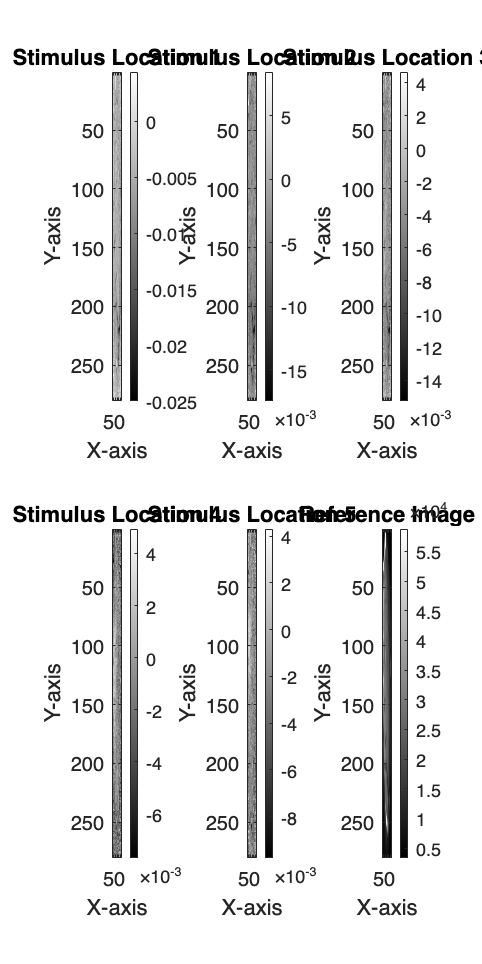

%% Visualize Results
% Average Image Across All Frames
avgImage = mean(mean(session, 3), 4); 
avgImage = imgaussfilt(avgImage);

figure('Position', [10 10 750 1500]);
hold on;
for locNum = 1:nStimLocs
    subplot(2, 3, locNum);
    imagesc(imgaussfilt(mapData(:, :, locNum), 0.5));
    colormap('gray');
    colorbar;
    title(['Stimulus Location ', num2str(locNum)]);
    xlabel('X-axis'); 
    ylabel('Y-axis');
end

subplot(2, 3, 6);
imagesc(avgImage);
colormap('gray'); 
colorbar;
title('Reference Image');
xlabel('X-axis');
ylabel('Y-axis');
hold off; 

**4) Save the figure if needed: **

saveas(gcf, [sessionDate,'_',subjectID,'.png']); % we need to adjust the png size 